# Practica 1: Introducción a la Wavelet Toolbox de MATLAB

## Archivo Analisis1D.mlx 

CURSO MASTER CONJUNTO UPV-UV 2023-24

EJEMPLO PARA LA PRIMERA PRACTICA 14 DE FEBRERO DE 2024

Introduccion a la Wavelet Toolobox Transformada de wavelet discreta de una señal NIVEL 1 Y 2 PERFIL DE ENERGIA ACUMULADA DE LA SEÑAL Y DE LA TRANSFORMADA (sin ordenar de mayor a menor los valores absolutos de los coeficientes)

# Ejemplo 1:

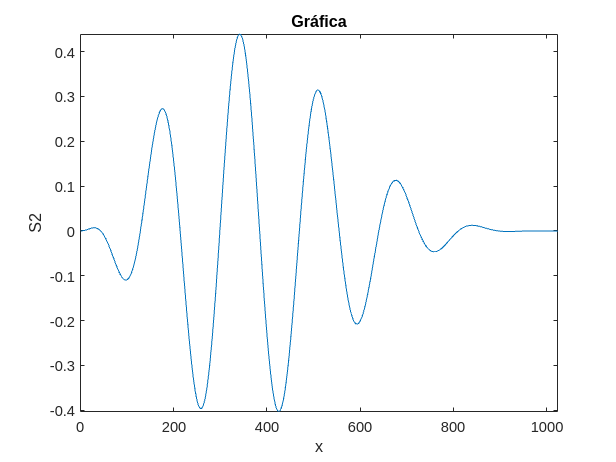


% Se genera la señal: 
x=linspace(0,1,1024);
s2= (20*x.^2).*((1-x).^4).*cos(12*pi*x);
%plot(x,s2)
plot(s2)
title('Gráfica')
xlabel('x')
ylabel('S2')
axis([0 length(s2) min(s2) max(s2)]); 

% Calculamos la transformada de Haar de la señal 's'
% NIVEL 1
%
s=s2;
w='haar';
Wavelet_utilizada=w

Wavelet_utilizada = 'haar'

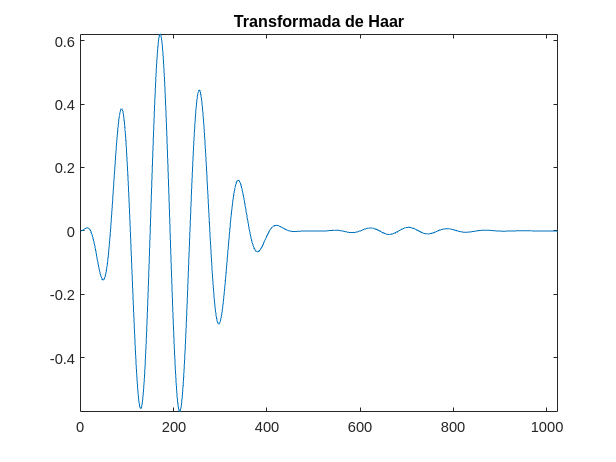

[C,L] = wavedec(s,1,w);
figure; plot(C); title('Transformada de Haar');
axis([0 length(C) min(C) max(C)])

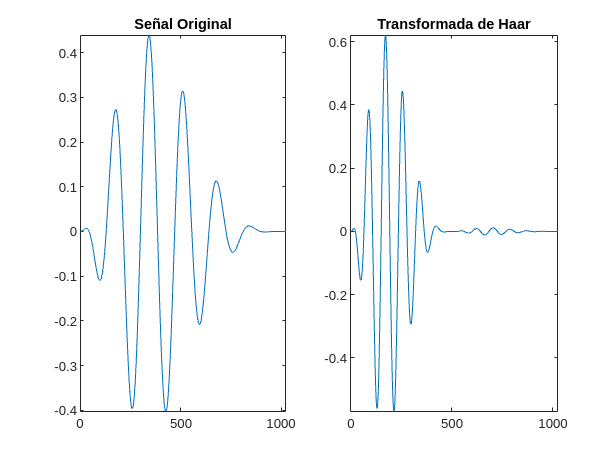


%La original y la transfromada juntas:
figure; subplot(1,2,1) 
plot(s); title('Señal Original');
axis([0 length(s) min(s) max(s)]);
subplot(1,2,2)
plot(C); title('Transformada de Haar')
axis([0 length(C) min(C) max(C)]);

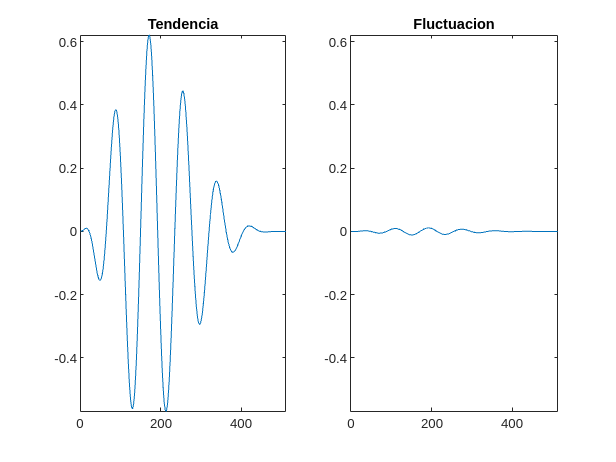

% Extraccion de coeficientes: 
cA1=appcoef(C,L,w,1);
cD1=detcoef(C,L,1);

figure; subplot(1,2,1) 
plot(cA1); title('Tendencia');
axis([0 length(cA1) min(cA1) max(cA1)]);
subplot(1,2,2)
plot(cD1); title('Fluctuacion')
axis([0 length(cD1) min(cA1) max(cA1)]); 

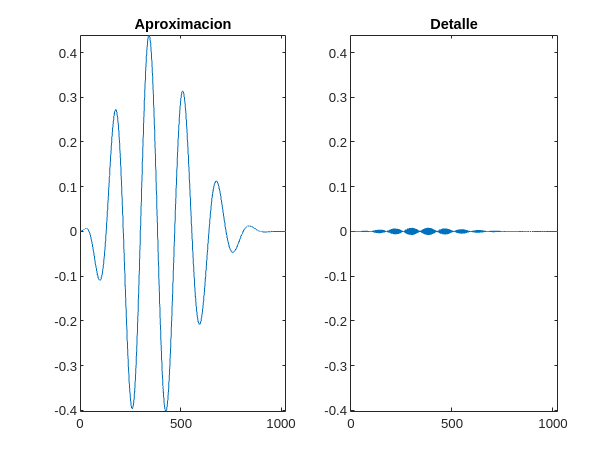

%RECONSTRUCCION:

A1=wrcoef('a',C,L,w,1);
D1=wrcoef('d',C,L,w,1);

figure;
subplot(1,2,1) 
plot(A1); title('Aproximacion');
axis([0 length(A1) min(A1) max(A1)]);
subplot(1,2,2)
plot(D1); title('Detalle')
axis([0 length(A1) min(A1) max(A1)]);

%axis([0 length(D1) -0.01 0.01];

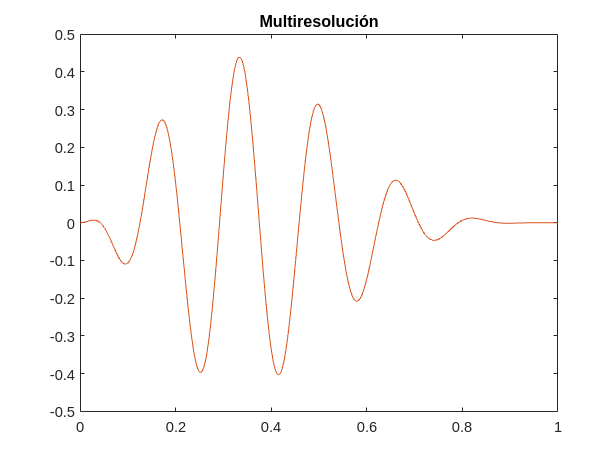

% ANALISIS DE MULTIRESOLUCION --- MRA
%La señal reconstruida por el MRA es:
R=A1+D1;
figure; plot(x,s,x,R); title('Multiresolución')

%Error1=rms(s,R)
%Error2= max(abs(R-s))

% OBTENCION DEL MAPA DE SIGNIFICANCIA DE Cd1

MAP=cD1>0; %SE PUEDE PONER Cd1>UMBRAL

% MAP esta formada solo por 1  y 0, 
%para ver por ejemplo 25 valores: MAP(1:25)


CEROS=length(cD1)-sum(MAP)  % numero de ceros de la subseñal de detalle; 

CEROS = 257

                            % Se puede usar el comando "nnz" para los
                            % elementos no nulos.
% comparar esto para distintas señales y tipo de wavelet
                
% se puede dar el valor como un tanto por uno o por ciento


% ENERGIA DE LA SEÑAL Y DE SU TRANSFORMADA Y PEFIL DE ENERGIA ACUMULADA

[energia_s]=energy(s)

energia_s = 31.7959

[energia_C]=energy(C)         

energia_C = 31.7959

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
perfil_energia_s

perfil_energia_s =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


perfil_energia_transf

perfil_energia_transf =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0020    0.0025    0.0029    0.0035    0.0041    0.0047    0.0054    0.0061    0.0068    0.0076    0.0083    0.0091


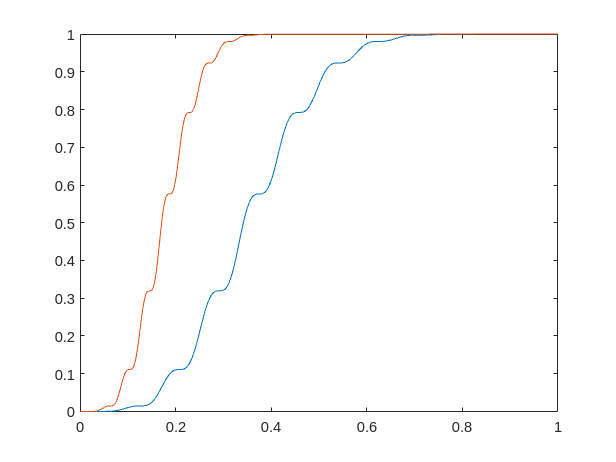

figure; plot(x,perfil_energia_s,x,perfil_energia_transf)

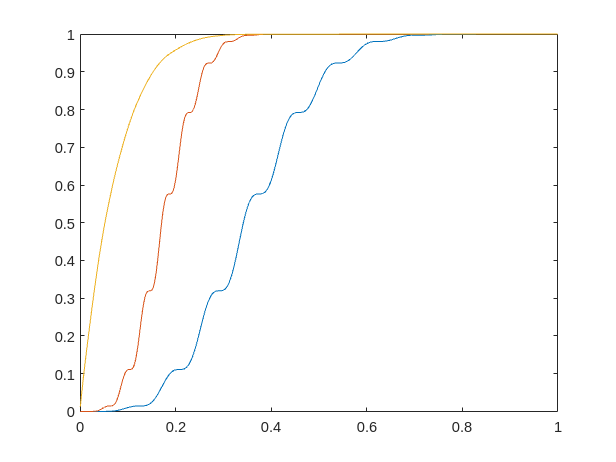



%Si queremos ordenar los valores absolutos (sort ordena de menos a mayor)
C_decreciente=sort(abs(C),'descend');
perfil_energia_transf_decreciente=cumenergy(C_decreciente);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf,x,perfil_energia_transf_decreciente)

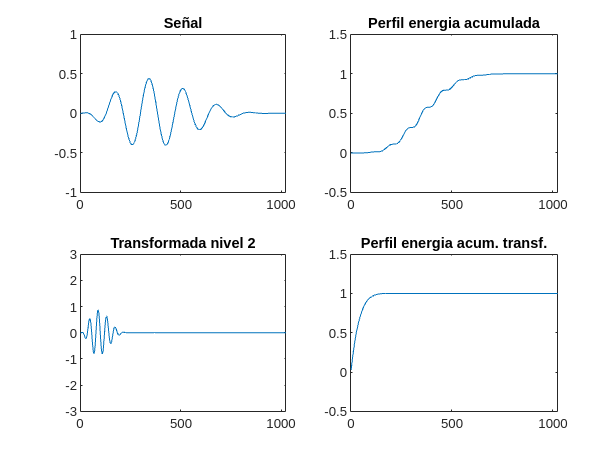

% TRANSFORMADA DE NIVEL 2 y perfil de energia acumulada

% Repetimos el analisis anterior pero con la transformada de nivel 2

% Tipo de wavelet
w='db3';
[C,L] = wavedec(s,2,w);

figure; subplot(2,2,1);
plot(s);
axis([0 length(s) -1 1]);
title('Señal');
subplot(2,2,2);
plot(cumenergy(s));
axis([0 length(s) -0.5 1.5]);
title('Perfil energia acumulada');
subplot(2,2,3);
plot(C);
axis([0 length(s) -3 3]);
title('Transformada nivel 2');
subplot(2,2,4);
plot(cumenergy(sort(abs(C),'descend')));
axis([0 length(s) -0.5 1.5]);
title('Perfil energia acum. transf.'); 


% SUGERENCIA DE EJERCICIOS
% Calcular el perfil de energia acumulada para diferentes señales y
% diferentes wavelets comparando el resultado.

# DEFINICION DE LAS FUNCIONES NECESARIAS, ENERGY Y CUMENERGY

SE PUEDEN DEFINIR AL FINAL DEL ARCHIVO MLX ACABANDOLAS CON "end". SIN EMBARGO ES MEJOR TENERLAS COMO ARCHIVOS INDEPENDIENTES .M O .MLX PARA NO TENER QUE COPIARLAS AL FINAL DE CADA EJERCICIO.

function [y] = energy(x)
%ENERGY Computes the energy of a signal.
%  y = ENERGY(x) returns the energy of x.
%  The energy computed as the sum of the 
%  square of the elements of x.

%   See also CUMENERGY.

y = norm(x)^2;
end
function [y] = cumenergy(x)
%CUMENERGY Computes the normalized cumulative energy profile.
%  y = CUMENERGY(x) creates a vector y with the normalized
%  cumulative energy profile of vector x.

%   See also ENERGY.

y = cumsum(x.^2)/(norm(x)^2);
end
